# **Homework 2 Orbital Dynamics - Interplanetary flight**

Student 1: Mario Barrantes Mellado 100471762

Student 2: Artem Lorenzo Lymar 100471784

## DATA OF THE PROBLEM

The date is January 1, 2312. A spaceship is planning a trip from Venus low orbit to Mercury low orbit, with the data below:

close all; clear all; clc;

% Parameters of orbit around Venus
a_V = 10000; % 
e_V = 0; % circular orbit
Omega_V = deg2rad(30); % [deg]->[rad] 
i_V = deg2rad(15); % [deg]->[rad] 

% Parameters of orbit around Mercury
a_M = 5000; % 
e_M = 0; % circular orbit
Omega_M = deg2rad(50); % [deg]->[rad] 
i_M = deg2rad(-40); % [deg]->[rad] 

% Gravitational Parameters
mu_V = 3.24859e5;  % [km^3/s^2]
mu_M = 0.220318e5; % [km^3/s^2]
mu_S = 1327120e5;  % [km^3/s^2]

### a) Implement the following functions

####     i) Dt = tof(mu,a,e,theta1,theta2)

% theta1 = deg2rad(10); % [deg]->[rad] 
% theta2 = deg2rad(30); % [deg]->[rad] 
% Dt = functionshw2.tof(mu_V, a_V, e_V, theta1, theta2); % Time of travel between theta1 and theta2 [s]
% fprintf('\nTime of flight = %.4f s = %.4f days\n', Dt, Dt/86400);

####  **ii) [a,e,Omega,i,omega,theta1,theta2] = Lambert conic(r1,r2,eT,k)**

    Function to compute the COE of the transfer trajectory (with a in km and angles in rad) between position vectors r1 and r2 (in km), as a function of the transverse eccentricity component, eT. Vector k defines the positive direction of the orbital plane normal and therefore selects between short and long arc solutions.

% r1 = [8945.34;5000;3000]; %km
% r2 = [7214.83899;2000;8249.64731]; %km
% eT = 0.4; %
% k = cross(r1,r2)/norm(cross(r1,r2)); % Normal vector to orbit plane
% [a, e, Omega, i, omega, theta1, theta2] = functionshw2.Lambert_conic(r1, r2, eT, k);

####  **iii) [a,e,Omega,i,omega,theta1,theta2] = Lambert solve(mu,r1,r2,Dt,k)**

Solve Lambert’s problem using the previous two functions. Internally, the function should use the bisection method. Restrict the search to elliptic solutions. The units of input and output arguments just be the same as in previous functions.

% Dt = functionshw2.tof(mu_V, a, e, theta1, theta2);
% fprintf('\nTarget time of flight = %.4f s\n', Dt);
% [a_s, e_s, Omega_s, i_s, omega_s, theta1_s, theta2_s, eT_lambert] = functionshw2.Lambert_solve(mu_V, r1, r2, Dt, k);

To verify Lambert_solve is correct we build a test case using `r1`, `r2` and `Dt` derived from a known orbit with `eT = 0.4` (from question a.ii). If the solver correctly recovers the same orbital elements and time of flight, therefore this function is OK.

% % tof matches input Dt?
% Dt_check = functionshw2.tof(mu_V, a_s, e_s, theta1_s, theta2_s);
% fprintf('Verification: tof(solution) = %.4f s  (target = %.4f s)\n', Dt_check, Dt);
% fprintf('Error = %.6f s\n', abs(Dt_check - Dt));

### b) [theta, Dv] = hyperbola(mu, a, e, Omega, i, omega, $\textbf{v}_h$)

Finding the parking orbit true anomaly, $\theta$ (rad), and the injection impulse vector, $\Delta \text{v}$ (km/s.), to go from parking orbit to escape hyperbola.

% r_park = 5000; % radius of parking orbit [km] = pericenter of hyperbolic scape trajectory
% e_park = 1; % parking orbit is circular
% a_park = r_park; % parking orbit is circular 
% mu_park = mu_V; % change depending on central body
% vh_park = sqrt(-mu_park/a_park); % hyperbolic excess velocity [km/s] - must be a vector!!
% Omega_park = 1; %[rad]
% i_park = 1; %[rad]
% omega_park = 1; %[rad]
% [theta, Dv] = functionshw2.hyperbola(mu_park, a_park, e_park, Omega_park, i_park, omega_park, vh_park);

### c) Creating meshgrid of departing and arriving times

`from Horizons Database`

`2312-Jan-01 (wrt to solar system barycenter)`

 `EC     Eccentricity, e`

 `QR     Periapsis distance, q (km)`

 `IN     Inclination w.r.t X-Y plane, i (degrees)`

 `OM     Longitude of Ascending Node, OMEGA, (degrees)`

 `W      Argument of Perifocus, w (degrees)`

 `Tp     Time of periapsis (Julian Day Number)`

 `N      Mean motion, n (degrees/sec)`

 `MA     Mean anomaly, M (degrees)`

 `TA     True anomaly, nu (degrees)`

 `A      Semi-major axis, a (km)`

 `AD     Apoapsis distance (km)`

 `PR     Sidereal orbit period (sec)`

### `Venus``:`

`Position & velocity wrt solar system barycenter`

`X =-6.477298847799687E+07 Y =-8.589866827531046E+07 Z = 2.487725783413380E+06`

`VX= 2.763672319058894E+01 VY=-2.134982207311649E+01 VZ=-1.898103269009142E+00`

`COE`

`EC= 6.648873891508952E-03 QR= 1.074886038804520E+08 IN= 3.391703026181389E+00`

`OM= 7.581101440068313E+01 W = 5.581930528473209E+01 Tp=  2565436.879091387149`

`N = 1.854340700281030E-05 MA= 1.003281115935119E+02 TA= 1.010765348519463E+02`

`A = 1.082080656630900E+08 AD= 1.089275274457280E+08 PR= 1.941390813163088E+07`

% Collecting data from Horizons Database
r_V0 = [-6.477298847799687E+07;-8.589866827531046E+07;2.487725783413380E+06]; %[km] wrt to solar center barycenter
v_V0 = [2.763672319058894E+01;-2.134982207311649E+01;-1.898103269009142E+00]; %[km/s]

e_V0 = 6.648873891508952E-03;              % Eccentricity [-]
Omega_V0 = deg2rad(7.581101440068313E+01); % RAAN [rad]
rp_V0 = 1.074886038804520E+08;             % Periapsis distance [km]
ra_V0 = 1.089275274457280E+08;             % Apoapsis distance [km] 
i_V0 = deg2rad(3.391703026181389E+00);     % Inclination [rad]
omega_V0 = deg2rad(5.581930528473209E+01); % Argument of periapsis [rad]
a_V0 = 1.082080656630900E+08;              % Semimajor axis [km]
theta_V0 = deg2rad(1.010765348519463E+02); % True anomaly [rad]
t_V0 = 1.941390813163088E+07;              % Sidereal orbit period [s]

### `Mercury``:`

`Position & velocity wrt solar system barycenter`

`X = 5.045410505191125E+07 Y = 1.167075906445298E+07 Z =-3.612451197805805E+06`

`VX=-2.031051711521749E+01 VY= 4.959234998501598E+01 VZ= 5.918521798192085E+00`

`COE`

`EC= 2.056883622610541E-01 QR= 4.599785193023808E+07 IN= 6.986345342226389E+00`

`OM= 4.793837544937558E+01 W = 3.001538899912408E+01 Tp=  2565510.565141667612`

`N = 4.736510971223164E-05 MA= 3.147176175204951E+02 TA= 2.947317339757159E+02`

`A = 5.790907465635732E+07 AD= 6.982029738247657E+07 PR= 7.600531323313562E+06`

r_M = [5.045410505191125E+07;1.167075906445298E+07;-3.612451197805805E+06];
v_M = [-2.031051711521749E+01;4.959234998501598E+01;5.918521798192085E+00];

e_M0 = 2.056883622610541E-01;              % Eccentricity [-]
Omega_M0 = deg2rad(4.793837544937558E+01); % RAAN [rad]
rp_M0 = 4.599785193023808E+07;             % Periapsis distance [km]
ra_M0 = 6.982029738247657E+07;             % Apoapsis distance [km] 
i_M0 = deg2rad(6.986345342226389E+00);     % Inclination [rad]
omega_M0 = deg2rad(3.001538899912408E+01); % Argument of periapsis [rad]
a_M0 = 5.790907465635732E+07;              % Semimajor axis [km]
theta_M0 = deg2rad(2.947317339757159E+02); % True anomaly [rad]
t_M0 = 7.600531323313562E+06;              % Sidereal orbit period [s]

We can see how Venus' orbit around the Sun is almost circular, while Mercury's has some (but little) eccentricity. These facts will be seen later in the 3D plot of the transfer orbit.

Time grid

t0 = 0;                         % [s] t0 = Jan 1 2312
t_depart = (0:1:365) * 86400;   % departure times [s] 2312 is leap year -> 366 days - tf = Dec 31 2312
t_travel = (60:1:90) * 86400;   % travel times [s], 60-90 days

[T_dep, T_trav] = meshgrid(t_depart, t_travel);  % [31 x 366] grids

Propagating planet positions at each grid node

r_Venus_grid   = zeros(3, size(T_dep,1), size(T_dep,2));
r_Mercury_grid = zeros(3, size(T_dep,1), size(T_dep,2));

for i = 1:size(T_dep,1)
    for j = 1:size(T_dep,2)
        t_d = T_dep(i,j);         % departure time [s]
        t_a = t_d + T_trav(i,j);  % arrival time = departure time + travel time [s]

        % Propagate Venus from 1-1-2312 to departure time
        theta_V = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, t_d);
        [r_Venus_grid(:,i,j), ~] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V, mu_S); 
        % theta_V and not theta_V0 - propagated to get complete orbit
        % rest of COE are constant regardless of time
        % same for mercury
        % Propagate Mercury from 1-1-2312 to arrival time
        theta_M = functionshw2.propagate(mu_S, a_M0, e_M0, theta_M0, t_a);
        [r_Mercury_grid(:,i,j), ~]= functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_M, mu_S);
    end
end

### d) Porkchop plot

%% Task (d) - Porkchop Plot of total Delta-V cost
% Venus (departure) -> Mercury (arrival)
% For each (t_depart, t_travel) node, computes total DV = DV_dep + DV_arr for both short and long arc Lambert solutions.

% Pre-allocate DV grids 
DV_short = nan(size(T_dep));   % [31 x 365]
DV_long  = nan(size(T_dep));   % [31 x 365]

for i = 1:size(T_dep,1)        % travel time index
    for j = 1:size(T_dep,2)    % departure day index

        t_d = T_dep(i,j); % departure time [s]
        t_a = t_d + T_trav(i,j); % arrival time [s]

        % Venus at departure
        theta_V_dep = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, t_d);
        [r1, v1] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V_dep, mu_S);

        % Mercury at arrival
        theta_M_arr = functionshw2.propagate(mu_S, a_M0, e_M0, theta_M0, t_a);
        [r2, v2] = functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_M_arr, mu_S);

        r1 = r1(:);  v1 = v1(:);
        r2 = r2(:);  v2 = v2(:);                                                  

        % Time of flight in seconds
        Dt = T_trav(i,j);

    %%% computing 2 arcs per node (short+long) %%%

    % plane normals (short arc / long arc) -
    k_cross = cross(r1, r2);
    if norm(k_cross) < 1e-6
        continue   % r1 and r2 are collinear, skip
    end

    k_short =  k_cross / norm(k_cross);   % short arc normal
    k_long  = -k_short;   % long arc normal (opposite)

    % SHORT ARC
    try
        [a_tr, e_tr, Om_tr, i_tr, om_tr, th1_tr, th2_tr] = functionshw2.Lambert_solve(mu_S, r1, r2, Dt, k_short);

        [~, v_dep_tr] = functionshw2.coe2rv(a_tr, e_tr, Om_tr, i_tr, om_tr, th1_tr, mu_S);
        [~, v_arr_tr] = functionshw2.coe2rv(a_tr, e_tr, Om_tr, i_tr, om_tr, th2_tr, mu_S);

        vh_dep = v_dep_tr(:) - v1;
        vh_arr = v_arr_tr(:) - v2;

        [~, Dv_dep] = functionshw2.hyperbola(mu_V, a_V, e_V, Omega_V, i_V, 0, vh_dep);
        [~, Dv_arr] = functionshw2.hyperbola(mu_M, a_M, e_M, Omega_M, i_M, 0, vh_arr);

        DV_short(i,j) = norm(Dv_dep) + norm(Dv_arr);
    catch ME_s
        % No elliptic short-arc solution — leaving as NaN
    end

    % LONG ARC
    try
        [a_tr, e_tr, Om_tr, i_tr, om_tr, th1_tr, th2_tr] = functionshw2.Lambert_solve(mu_S, r1, r2, Dt, k_long);

        [~, v_dep_tr] = functionshw2.coe2rv(a_tr, e_tr, Om_tr, i_tr, om_tr, th1_tr, mu_S);
        [~, v_arr_tr] = functionshw2.coe2rv(a_tr, e_tr, Om_tr, i_tr, om_tr, th2_tr, mu_S);

        vh_dep = v_dep_tr(:) - v1;
        vh_arr = v_arr_tr(:) - v2;

        [~, Dv_dep] = functionshw2.hyperbola(mu_V, a_V, e_V, Omega_V, i_V, 0, vh_dep);
        [~, Dv_arr] = functionshw2.hyperbola(mu_M, a_M, e_M, Omega_M, i_M, 0, vh_arr);

        DV_long(i,j) = norm(Dv_dep) + norm(Dv_arr);
    catch ME_l
        % No elliptic long-arc solution — leaving as NaN
    end
    
    end

    % Progress indicator
    if mod(i,5) == 0
        fprintf('Progress: travel time row %d / %d done\n', i, size(T_dep,1));
    end
end

Progress: travel time row 5 / 31 done
Progress: travel time row 10 / 31 done
Progress: travel time row 15 / 31 done
Progress: travel time row 20 / 31 done
Progress: travel time row 25 / 31 done
Progress: travel time row 30 / 31 done


%% TEST SECTION - test a single arbitrary node first
ii_test = 16;   % middle travel time (75 days)
jj_test = 1;    % first departure day

r1_test = r_Venus_grid(:, ii_test, jj_test);
r2_test = r_Mercury_grid(:, ii_test, jj_test);
Dt_test = T_trav(ii_test, jj_test);

k_test = cross(r1_test, r2_test)/norm(cross(r1_test, r2_test));
try
    [a_t, e_t, Omega_t, i_t, omega_t, th1_t, th2_t] = functionshw2.Lambert_solve(mu_S, r1_test, r2_test, Dt_test, k_test);
    fprintf('Lambert runs OK: a=%.4e km, e=%.6f\n', a_t, e_t);

    % Test velocities
    [~, v1_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th1_t, mu_S);
    [~, v2_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th2_t, mu_S);
    fprintf('v1_transfer = [%.4f, %.4f, %.4f] km/s\n', v1_t);
    fprintf('v2_transfer = [%.4f, %.4f, %.4f] km/s\n', v2_t);

    % Test planet velocities
    theta_V_dep = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, T_dep(ii_test,jj_test));
    [~, v1_V] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V_dep, mu_S);
    fprintf('v_Venus = [%.4f, %.4f, %.4f] km/s\n', v1_V);

    theta_M_arr = functionshw2.propagate(mu_S, a_M0, e_M0, theta_M0, T_dep(ii_test,jj_test)+Dt_test);
    [~, v2_M] = functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_M_arr, mu_S);
    fprintf('v_Mercury = [%.4f, %.4f, %.4f] km/s\n', v2_M);

    % Hyperbolic excess velocities
    vh_dep = v1_t - v1_V;
    vh_arr = (v2_t - v2_M);
    fprintf('vh_dep = [%.4f, %.4f, %.4f] km/s\n', vh_dep);
    fprintf('vh_dep magnitude = %.4f km/s\n', norm(vh_dep));
    fprintf('vh_arr = [%.4f, %.4f, %.4f] km/s\n', vh_arr);
    fprintf('vh_arr magnitude = %.4f km/s\n', norm(vh_arr));

    % Test hyperbola
    [theta_burn, Dv_dep] = functionshw2.hyperbola(mu_V, a_V, e_V, Omega_V, i_V, 0, vh_dep); % what is omega_V=0(undetermined since parking orbit is circular)
    [~,          Dv_arr] = functionshw2.hyperbola(mu_M, a_M, e_M, Omega_M, i_M, 0, -vh_arr); % -vh_arr
    fprintf('DV_dep = %.4f km/s\n', norm(Dv_dep));
    fprintf('DV_arr = %.4f km/s\n', norm(Dv_arr));
    fprintf('DV_total = %.4f km/s\n', norm(Dv_dep)+norm(Dv_arr));

catch
    fprintf('ERROR: %s\n', ME.message);
end

Lambert runs OK: a=7.4448e+07 km, e=0.637437


v1_transfer = [9.7818, -23.7795, -2.4727] km/s


v2_transfer = [3.3185, 49.8962, 2.4793] km/s


v_Venus = [27.6327, -21.3602, -1.8980] km/s


v_Mercury = [23.1525, 38.2175, 1.0311] km/s


vh_dep = [-17.8509, -2.4192, -0.5747] km/s


vh_dep magnitude = 18.0233 km/s


vh_arr = [-19.8340, 11.6787, 1.4482] km/s


vh_arr magnitude = 23.0625 km/s


DV_dep = 14.7838 km/s


DV_arr = 21.7757 km/s


DV_total = 36.5595 km/s


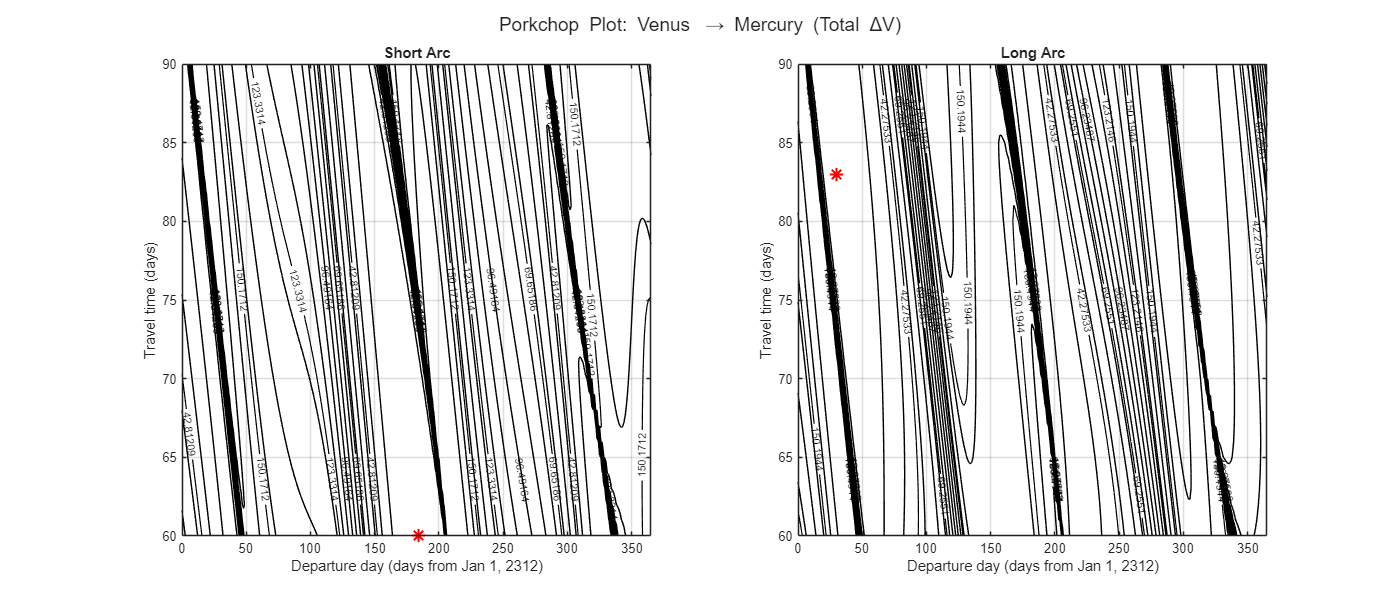

%%% CONT'D PORKCHOP PLOT %%%
% Convert departure times from seconds to days for readable axis
dep_days   = t_depart / 86400;
trav_days  = t_travel / 86400;

figure('Name','Porkchop Plot - Venus to Mercury','Position',[100 100 1400 600]);
levels = 15;      % fewer contours
label_levels = 5; % fewer labels

% Short arc
subplot(1,2,1);
contour(dep_days, trav_days, DV_short, levels, 'LineColor',[0 0 0],'LineWidth',0.6);
hold on;
[cs, h] = contour(dep_days, trav_days, DV_short, label_levels, 'k','LineWidth',0.9);
clabel(cs, h, 'Color','k','FontSize',8);

xlabel('Departure day (days from Jan 1, 2312)');
ylabel('Travel time (days)');
title('Short Arc');
grid on;

% finding minimum DeltaV in short-arc
[min_val_s, idx_s] = min(DV_short(:));
[ri_s, ci_s] = ind2sub(size(DV_short), idx_s);
plot(dep_days(ci_s), trav_days(ri_s), 'r*', 'MarkerSize', 10, 'LineWidth', 1.5);

% Long arc
subplot(1,2,2);
contour(dep_days, trav_days, DV_long, levels, 'LineColor',[0 0 0],'LineWidth',0.6);
hold on;
[cs, h] = contour(dep_days, trav_days, DV_long, label_levels, 'k','LineWidth',0.9);
clabel(cs, h, 'Color','k','FontSize',8);

xlabel('Departure day (days from Jan 1, 2312)');
ylabel('Travel time (days)');
title('Long Arc');
grid on;

% finding minimum DeltaV in long-arc
[min_val_l, idx_l] = min(DV_long(:));
[ri_l, ci_l] = ind2sub(size(DV_long), idx_l);
plot(dep_days(ci_l), trav_days(ri_l), 'r*', 'MarkerSize', 10, 'LineWidth', 1.5);

sgtitle('Porkchop Plot: Venus \rightarrow Mercury (Total \DeltaV)', 'FontSize', 14);

fprintf('\n-- Short Arc Optimum --\n');


-- Short Arc Optimum --


fprintf('Departure day: day %d of year 2312\n', round(dep_days(ci_s)));

Departure day: day 184 of year 2312


fprintf('Travel time: %d days\n', round(trav_days(ri_s)));

Travel time: 60 days


fprintf('Total DV: %.4f km/s\n', min_val_s);

Total DV: 15.9723 km/s


fprintf('\n-- Long Arc Optimum --\n');


-- Long Arc Optimum --


fprintf('Departure day: day %d of year 2312\n', round(dep_days(ci_l)));

Departure day: day 30 of year 2312


fprintf('Travel time: %d days\n', round(trav_days(ri_l)));

Travel time: 83 days


fprintf('Total DV: %.4f km/s\n', min_val_l);

Total DV: 15.2956 km/s


According to the results obtained from the Porkchop plot, the optimum travel (the one requiring a smallest $\Delta V$) is the one following the short arc trajectory and departing on day 184 of 2312 and the interplanetary flight takes 60 days to arrive to Mercury's parking orbit. It is worth mentioning that the obtained travel time of 60 days is actually the lowerbound of the range used for the optimization process, which may indicate that the real optimum travel time is below this value, so maybe a wider range of times should be tried. From literature, the pure Hohmann transfer for going from Venus to Mercury takes around 65 days, which is not far from our solution. 

**PLOT OF VENUS & MERCURY ORBITING AROUND THE SUN AND TRANSFER ORBIT**

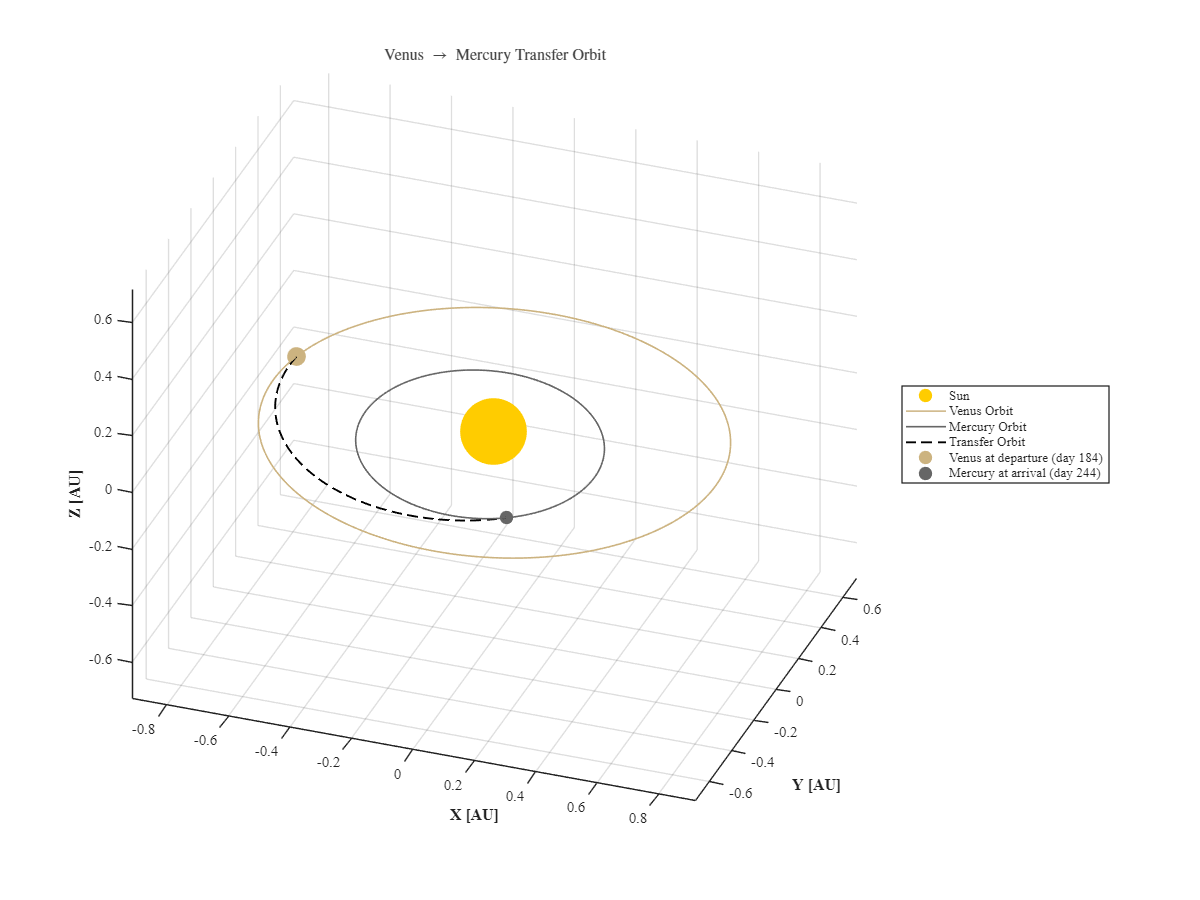

AU = 1.495978707e8; % km

fig = figure('Color','w','Position',[100 100 1200 900]);
ax = axes(fig);
hold(ax,'on');
axis(ax,'equal');
grid(ax,'on');
set(ax,'FontName','Times','FontSize',11,'LineWidth',1);
view(20,30);

% Sun (bigger, subtle) 
plot3(0,0,0,'o','MarkerSize', 50,'MarkerFaceColor',[1 0.8 0],'MarkerEdgeColor','none','DisplayName','Sun');

% Venus orbit
theta_Venus = linspace(0, 2*pi, 1000);
p_Venus = a_V0 * (1 - e_V0^2);
r_Venus_orbit = p_Venus ./ (1 + e_V0 * cos(theta_Venus));
for m = 1:length(theta_Venus)
    [r_V_inertial(:,m), ~] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_Venus(m), mu_S);
end
plot3(r_V_inertial(1,:)/AU, r_V_inertial(2,:)/AU, r_V_inertial(3,:)/AU, 'Color', [0.80, 0.70, 0.50] ,'LineWidth',1.2,'DisplayName','Venus Orbit');

% Mercury orbit
theta_Mercury = linspace(0, 2*pi, 1000);
p_Mercury = a_M0 * (1 - e_M0^2);
r_Mercury_orbit = p_Mercury ./ (1 + e_M0 * cos(theta_Mercury));
for m = 1:length(theta_Mercury)
    [r_M_inertial(:,m), ~] = functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_Mercury(m), mu_S);
end
plot3(r_M_inertial(1,:)/AU, r_M_inertial(2,:)/AU, r_M_inertial(3,:)/AU, 'Color', [0.4, 0.4, 0.4],'LineWidth',1.2,'DisplayName','Mercury Orbit');

% Transfer orbit (arc only)

% Selecting departure day and travel time from optimum point of porkchop plot
dep_day_opt = round(dep_days(ci_s));      % optimal departure day
trav_time_opt = round(trav_days(ri_s));   % optimal travel time

% Find the corresponding indices in grids
[~, j_opt] = min(abs(t_depart/86400 - dep_day_opt));
[~, i_opt] = min(abs(t_travel/86400 - trav_time_opt));

t_d = T_dep(i_opt, j_opt);    % departure time [s]
t_a = t_d + T_trav(i_opt, j_opt);  % arrival time [s]
Dt_opt = T_trav(i_opt, j_opt);

%% Propagate planets to departure/arrival times
theta_V_dep = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, t_d);
[r1_opt, v1_opt] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V_dep, mu_S);

theta_M_arr = functionshw2.propagate(mu_S, a_M0, e_M0, theta_M0, t_a);
[r2_opt, v2_opt] = functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_M_arr, mu_S);

r1_opt = r1_opt(:); v1_opt = v1_opt(:);
r2_opt = r2_opt(:); v2_opt = v2_opt(:);

%% Solve Lambert to get transfer orbit
k_opt = cross(r1_opt, r2_opt) / norm(cross(r1_opt, r2_opt));
[a_tr, e_tr, Omega_tr, i_tr, omega_tr, theta1_tr, theta2_tr] = functionshw2.Lambert_solve(mu_S, r1_opt, r2_opt, Dt_opt, k_opt);

% Generate points along the transfer orbit from theta1 to theta2 - For elliptic transfer, theta goes from theta1_tr to theta2_tr
if theta2_tr > theta1_tr
    theta_transfer = linspace(theta1_tr, theta2_tr, 500);
else
    % Handle case where theta wraps around 2*pi
    theta_transfer = linspace(theta1_tr, theta1_tr + (theta2_tr - theta1_tr + 2*pi), 500);
    theta_transfer = mod(theta_transfer, 2*pi);
end

for m = 1:length(theta_transfer)
    [r_tr_inertial(:,m), ~] = functionshw2.coe2rv(a_tr, e_tr, Omega_tr, i_tr, omega_tr, theta_transfer(m), mu_S);
end

plot3(r_tr_inertial(1,:)/AU, r_tr_inertial(2,:)/AU, r_tr_inertial(3,:)/AU, 'Color',[0 0 0],'LineWidth', 1.4,'LineStyle','--','DisplayName','Transfer Orbit');

% Departure / Arrival markers (Venus bigger than Mercury) 
plot3(r1_opt(1)/AU, r1_opt(2)/AU, r1_opt(3)/AU, 'o', 'MarkerSize', 14,'MarkerFaceColor', [0.80, 0.70, 0.50] ,'MarkerEdgeColor','none', 'DisplayName', sprintf('Venus at departure (day %d)', dep_day_opt));
plot3(r2_opt(1)/AU, r2_opt(2)/AU, r2_opt(3)/AU, 'o', 'MarkerSize', 10,'MarkerFaceColor', [0.4 0.4 0.4],'MarkerEdgeColor','none', 'DisplayName', sprintf('Mercury at arrival (day %d)', dep_day_opt+ trav_time_opt));

% Labels 
xlabel('X [AU]','FontSize',12,'FontWeight','bold');
ylabel('Y [AU]','FontSize',12,'FontWeight','bold');
zlabel('Z [AU]','FontSize',12,'FontWeight','bold');

title('Venus $\rightarrow$ Mercury Transfer Orbit','Interpreter','latex');

legend('Location','eastoutside','FontSize',10);

**Sizes of Mercury, Venus and Sun are not real

Here we can perfectly see the transfer maneuver, departing form Venus parking orbit on day 184, taking 60 days to arrive to Mercury parking orbit, on day 244. The transfer trajectory is the short-arc of the ellipse, which can be seen on the plot.

**DEPARTURE AND ARRIVAL PROBLEMS**

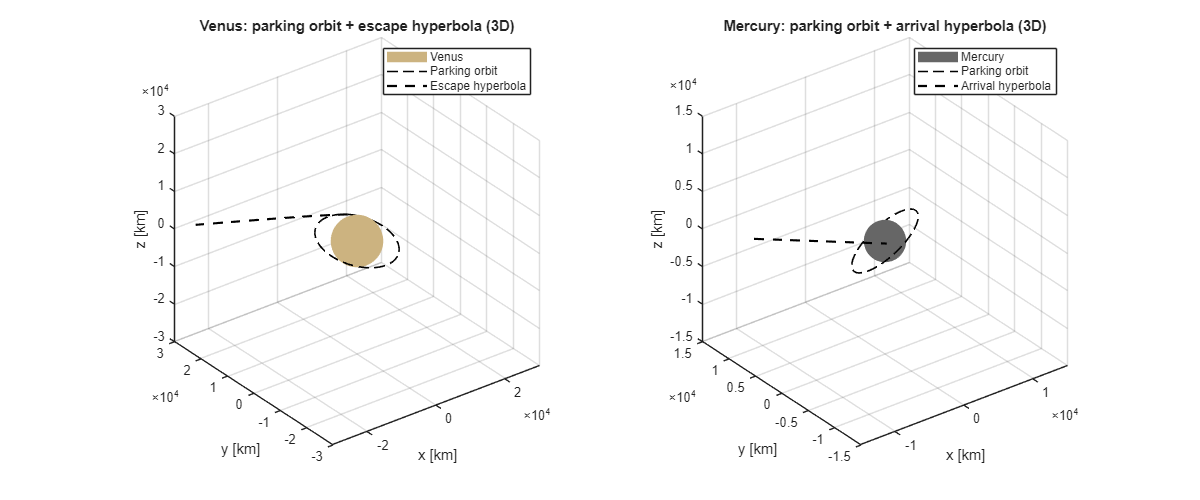

%% DEPARTURE AND ARRIVAL PROBLEMS (3D PLOT) %%

% Colors
cV = [0.80, 0.70, 0.50]; % Venus    
cM = [0.4, 0.4, 0.4];    % Mercury
cH = [0 0 0];            % Hyperbola (transfer orbit color)

figure('Color','w','Position',[200 200 1200 500]);

%%%% VENUS (departure problem) %%%%%
ax1 = subplot(1,2,1); hold on; axis equal; grid on;
title('Venus: parking orbit + escape hyperbola (3D)');
view(3);

R_V = 6051.8; % Venus radius [km]

[r_burn_V, v_park_V] = functionshw2.coe2rv(a_V, e_V, Omega_V, i_V, 0, theta_V_dep, mu_V);
v_hyp_V = v_park_V + Dv_dep; % Velocidad post-maniobra

h_vec_V = cross(r_burn_V, v_hyp_V);
h_hat_V = h_vec_V / norm(h_vec_V);

e_vec_V = ((norm(v_hyp_V)^2 - mu_V/norm(r_burn_V))*r_burn_V - dot(r_burn_V, v_hyp_V)*v_hyp_V) / mu_V;
e_mag_V = norm(e_vec_V);
e_hat_V = e_vec_V / e_mag_V;

p_hat_V = cross(h_hat_V, e_hat_V);
R_perif2eci_V = [e_hat_V, p_hat_V, h_hat_V];

p_h_V = (norm(h_vec_V)^2) / mu_V;
theta_asymp_V = acos(-1/e_mag_V);
theta_range_V = linspace(0, 0.95*theta_asymp_V, 500); 

r_local_V = zeros(3, length(theta_range_V));
for j = 1:length(theta_range_V)
    mag = p_h_V / (1 + e_mag_V*cos(theta_range_V(j)));
    r_local_V(:,j) = mag * [cos(theta_range_V(j)); sin(theta_range_V(j)); 0];
end
r_3D_V = R_perif2eci_V * r_local_V;

%plotting venus
[XS,YS,ZS] = sphere(60);
surf(R_V*XS, R_V*YS, R_V*ZS, 'FaceColor', cV, 'EdgeColor','none', 'FaceLighting','gouraud');

% parking orbit
th = linspace(0,2*pi,400);
orb_V = [a_V*cos(th); a_V*sin(th); zeros(size(th))];

Rot_Z_V = [cos(Omega_V) -sin(Omega_V) 0; sin(Omega_V) cos(Omega_V) 0; 0 0 1];
Rot_X_V = [1 0 0; 0 cos(i_V) -sin(i_V); 0 sin(i_V) cos(i_V)];
orb_V = Rot_Z_V * Rot_X_V * orb_V;
plot3(orb_V(1,:), orb_V(2,:), orb_V(3,:), 'k--','LineWidth',1.2);

% hyperbola
plot3(r_3D_V(1,:), r_3D_V(2,:), r_3D_V(3,:), '--', 'Color',cH,'LineWidth',1.6);

xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');
legend('Venus','Parking orbit','Escape hyperbola','Location','best');
xlim([-3*a_V 3*a_V]); ylim([-3*a_V 3*a_V]); zlim([-3*a_V 3*a_V]);


%%%% MERCURY (arrival problem) %%%%%
ax2 = subplot(1,2,2); hold on; axis equal; grid on;
title('Mercury: parking orbit + arrival hyperbola (3D)');
view(3);

R_M = 2439.7; % Mercury radius [km]

[r_burn_M, v_park_M] = functionshw2.coe2rv(a_M, e_M, Omega_M, i_M, 0, theta_M_arr, mu_M);
v_hyp_M = v_park_M + Dv_arr; % Velocidad pre-maniobra (en la hipérbola)

h_vec_M = cross(r_burn_M, v_hyp_M);
h_hat_M = h_vec_M / norm(h_vec_M);

e_vec_M = ((norm(v_hyp_M)^2 - mu_M/norm(r_burn_M))*r_burn_M - dot(r_burn_M, v_hyp_M)*v_hyp_M) / mu_M;
e_mag_M = norm(e_vec_M);
e_hat_M = e_vec_M / e_mag_M;

p_hat_M = cross(h_hat_M, e_hat_M);
R_perif2eci_M = [e_hat_M, p_hat_M, h_hat_M];

p_h_M = (norm(h_vec_M)^2) / mu_M;
theta_asymp_M = acos(-1/e_mag_M);
theta_range_M = linspace(-0.95*theta_asymp_M, 0, 500); 

r_local_M = zeros(3, length(theta_range_M));
for j = 1:length(theta_range_M)
    mag = p_h_M / (1 + e_mag_M*cos(theta_range_M(j)));
    r_local_M(:,j) = mag * [cos(theta_range_M(j)); sin(theta_range_M(j)); 0];
end
r_3D_M = R_perif2eci_M * r_local_M;

surf(R_M*XS, R_M*YS, R_M*ZS, 'FaceColor', cM, 'EdgeColor','none', 'FaceLighting','gouraud');

% parking orbit
orb_M = [a_M*cos(th); a_M*sin(th); zeros(size(th))];

Rot_Z_M = [cos(Omega_M) -sin(Omega_M) 0; sin(Omega_M) cos(Omega_M) 0; 0 0 1];
Rot_X_M = [1 0 0; 0 cos(i_M) -sin(i_M); 0 sin(i_M) cos(i_M)];

orb_M = Rot_Z_M * Rot_X_M * orb_M;
plot3(orb_M(1,:), orb_M(2,:), orb_M(3,:), 'k--','LineWidth',1.2);

% hyperbola
plot3(r_3D_M(1,:), r_3D_M(2,:), r_3D_M(3,:), '--', 'Color',cH,'LineWidth',1.6);

xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');
legend('Mercury','Parking orbit','Arrival hyperbola','Location','best');
xlim([-3*a_M 3*a_M]); ylim([-3*a_M 3*a_M]); zlim([-3*a_M 3*a_M]);

## **TEST SECTION**

%%% matlab built-in tests %%%
results = runtests('test_hw2');

Running test_hw2
........
Done test_hw2
__________



disp(table(results));

                             Name                              Passed    Failed    Incomplete    Duration       Details   
    _______________________________________________________    ______    ______    __________    _________    ____________

    {'test_hw2/test_venus_orbital_period'                 }    true      false       false       0.0028531    {1×1 struct}
    {'test_hw2/test_mercury_orbital_period'               }    true      false       false       0.0024225    {1×1 struct}
    {'test_hw2/test_venus_position_error_after_one_period'}    true      false       false       0.0041479    {1×1 struct}
    {'test_hw2/test_lambert_visviva_at_arrival'           }    true      false       false       0.0033332    {1×1 struct}
    {'test_hw2/test_lambert_r2_consistency'              

%%% more tests but coded %%%

Checking if results are physically realistic

% Max and min positions of Venus and Mercury should be inside the range of apoapsis-periapsis 
fprintf('Venus periapsis=%.3e km, Venus apoapsis=%.3e km\n', rp_V0, ra_V0);

Venus periapsis=1.075e+08 km, Venus apoapsis=1.089e+08 km


fprintf('Venus distance from Sun: min=%.3e km, max=%.3e km\n', ...
    min(min(squeeze(vecnorm(r_Venus_grid,1,1)))), ...
    max(max(squeeze(vecnorm(r_Venus_grid,1,1)))));

Venus distance from Sun: min=1.096e+08 km, max=1.594e+08 km


fprintf('Mercury: periapsis=%.3e km and apoapsis=%.3e km\n', rp_M0, ra_M0);

Mercury: periapsis=4.600e+07 km and apoapsis=6.982e+07 km


fprintf('Mercury distance from Sun: min=%.3e km, max=%.3e km\n', ...
    min(min(squeeze(vecnorm(r_Mercury_grid,1,1)))), ...
    max(max(squeeze(vecnorm(r_Mercury_grid,1,1)))));

Mercury distance from Sun: min=4.997e+07 km, max=9.681e+07 km


% Expected:
% Venus:   ~1.075e8 to ~1.089e8 km (low eccentricity)
% Mercury: ~4.6e7  to ~6.98e7  km (high eccentricity)
% For departure day 1, Venus position should be same for all travel times
diff_venus = squeeze(r_Venus_grid(:,:,1)) - r_Venus_grid(:,1,1);
fprintf('Venus position variation across departure times: %.6f km (should be ~0)\n', ...
    max(max(abs(diff_venus))));

Venus position variation across departure times: 0.000000 km (should be ~0)



% For fixed departure, Mercury position should change with travel time
r_M_dep1 = squeeze(r_Mercury_grid(:,:,1));  % all travel times, departure day 1
fprintf('Mercury position range for departure dates range:\n');

Mercury position range for departure dates range:


fprintf('x: [%.3e, %.3e] km\n', min(r_M_dep1(1,:)), max(r_M_dep1(1,:)));

x: [1.742e+06, 5.398e+07] km


fprintf('y: [%.3e, %.3e] km\n', min(r_M_dep1(2,:)), max(r_M_dep1(2,:)));

y: [-6.904e+07, 1.983e+07] km


% Venus orbital period ~224.7 days
% Mercury orbital period ~87.97 days
T_Venus = 2*pi*sqrt(a_V0^3/mu_S);
T_Mercury = 2*pi*sqrt(a_M0^3/mu_S);
fprintf('Venus period: %.2f days (expected 224.7)\n', T_Venus/86400);

Venus period: 224.70 days (expected 224.7)


fprintf('Mercury period: %.2f days (expected 87.97)\n', T_Mercury/86400);

Mercury period: 87.97 days (expected 87.97)


% After one full period, planet should return to same position
theta_V_check = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, T_Venus);
[r_V_check, ~] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V_check, mu_S);
[r_V_t0, ~] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V0, mu_S);
fprintf('Venus position error after one period: %.6f km (should be ~0)\n', norm(r_V_check - r_V_t0));

Venus position error after one period: 0.000000 km (should be ~0)


fprintf('Short arc DV range: %.4f to %.4f km/s\n', min(DV_short(:)), max(DV_short(:)));

Short arc DV range: 15.9723 to 177.0110 km/s


fprintf('Long arc  DV range: %.4f to %.4f km/s\n', min(DV_long(:)),  max(DV_long(:)));

Long arc  DV range: 15.2956 to 177.1742 km/s


%% TESTING LAMBERT %%
fprintf('Short arc: %d valid nodes out of %d\n', sum(~isnan(DV_short(:))), numel(DV_short));

Short arc: 11346 valid nodes out of 11346


fprintf('Long arc:  %d valid nodes out of %d\n', sum(~isnan(DV_long(:))),  numel(DV_long));

Long arc:  11346 valid nodes out of 11346


%% Check if planet velocities are correct
% Venus circular orbital speed should be ~35 km/s
% Mercury orbital speed should be ~40-60 km/s
fprintf('Venus orbital speed: %.2f km/s (expected ~35)\n', norm(v1_V));

Venus orbital speed: 34.98 km/s (expected ~35)


fprintf('Mercury orbital speed: %.2f km/s (expected ~40-60)\n', norm(v2_M));

Mercury orbital speed: 44.70 km/s (expected ~40-60)


%% Check if vh magnitudes are realistic - vh_dep and vh_arr should be ~3-10 km/s for inner solar system
fprintf('vh_dep magnitude: %.2f km/s (expected 3-10)\n', norm(vh_dep));

vh_dep magnitude: 18.02 km/s (expected 3-10)


fprintf('vh_arr magnitude: %.2f km/s (expected 3-10)\n', norm(vh_arr));

vh_arr magnitude: 23.06 km/s (expected 3-10)


%% Check if parking orbit ΔV are realistic - Each burn should be <10 km/s
fprintf('DV_dep: %.2f km/s (expected 1-5)\n', norm(Dv_dep));

DV_dep: 14.78 km/s (expected 1-5)


fprintf('DV_arr: %.2f km/s (expected 1-5)\n', norm(Dv_arr));

DV_arr: 21.78 km/s (expected 1-5)


%% Check mu_S - mu_S=1.327124e11 km^3/s^2
fprintf('mu_S = %.4e km^3/s^2 (expected 1.327e11)\n', mu_S);

mu_S = 1.3271e+11 km^3/s^2 (expected 1.327e11)


% Check transfer orbit velocity magnitudes
fprintf('v1_transfer magnitude: %.2f km/s\n', norm(v1_t));  % should be ~30-40 km/s

v1_transfer magnitude: 25.83 km/s


fprintf('v2_transfer magnitude: %.2f km/s\n', norm(v2_t));  % should be ~40-60 km/s

v2_transfer magnitude: 50.07 km/s


fprintf('v1_Venus magnitude: %.2f km/s\n', norm(v1_V));  % ~35 km/s

v1_Venus magnitude: 34.98 km/s


fprintf('v2_Mercury magnitude: %.2f km/s\n', norm(v2_M));  % ~47 km/s

v2_Mercury magnitude: 44.70 km/s


% Check vh components
fprintf('\nvh_dep = [%.2f, %.2f, %.2f] km/s\n', vh_dep);


vh_dep = [-17.85, -2.42, -0.57] km/s


fprintf('vh_arr = [%.2f, %.2f, %.2f] km/s\n', vh_arr);

vh_arr = [-19.83, 11.68, 1.45] km/s


% Check transfer orbit elements
fprintf('\nTransfer orbit:\n');


Transfer orbit:


fprintf('a = %.4e km\n', a_t);

a = 7.4448e+07 km


fprintf('e = %.6f\n', e_t);

e = 0.637437


fprintf('theta1 = %.4f deg\n', rad2deg(th1_t));

theta1 = 158.2488 deg


fprintf('theta2 = %.4f deg\n', rad2deg(th2_t));

theta2 = -116.6322 deg


% Full velocity check
fprintf('v1_transfer = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v1_t, norm(v1_t));

v1_transfer = [9.7818, -23.7795, -2.4727] km/s,  mag = 25.8314


fprintf('v2_transfer = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v2_t, norm(v2_t));

v2_transfer = [3.3185, 49.8962, 2.4793] km/s,  mag = 50.0679


fprintf('v1_Venus    = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v1_V, norm(v1_V));

v1_Venus    = [27.6327, -21.3602, -1.8980] km/s,  mag = 34.9775


fprintf('v2_Mercury  = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v2_M, norm(v2_M));

v2_Mercury  = [23.1525, 38.2175, 1.0311] km/s,  mag = 44.6954


% Vis-viva check at theta2
r2_mag = norm(r2_test);
v2_visviva = sqrt(mu_S*(2/r2_mag - 1/a_t));
fprintf('\nvis-viva speed at r2: %.4f km/s\n', v2_visviva);


vis-viva speed at r2: 50.0679 km/s


fprintf('norm(v2_transfer): %.4f km/s\n', norm(v2_t));

norm(v2_transfer): 50.0679 km/s


% Check r2 is consistent with theta2 (must be exactly equal)
p_t = a_t*(1-e_t^2);
r2_from_theta2 = p_t/(1+e_t*cos(th2_t));
fprintf('\nnorm(r2_Mercury) = %.4e km\n', norm(r2_test));


norm(r2_Mercury) = 6.1879e+07 km


fprintf('r(theta2) = %.4e km\n', r2_from_theta2);

r(theta2) = 6.1879e+07 km


%  Try long arc instead of short for Hohmman transfer
k_helio = -cross(r1, r2)/norm(cross(r1, r2));  % flip to long arc
[a_t, e_t, Omega_t, i_t, omega_t, th1_t, th2_t] = functionshw2.Lambert_solve(mu_S, r1, r2, Dt, k_helio);

[~, v1_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th1_t, mu_S);
[~, v2_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th2_t, mu_S);

vh_dep_long = v1_t - v1_V;
vh_arr_long = (v2_t - v2_M);

fprintf('vh_dep (long arc) = %.2f km/s\n', norm(vh_dep_long));

vh_dep (long arc) = 50.59 km/s


fprintf('vh_arr (long arc) = %.2f km/s\n', norm(vh_arr_long))

vh_arr (long arc) = 36.10 km/s


% Check angular separation between Mercury and transfer arrival point - If Mercury is far from where the spacecraft arrives, vh_arr will be huge

% Position on transfer orbit at theta2
p_t = a_t*(1-e_t^2);
r2_transfer_mag = p_t/(1+e_t*cos(th2_t));

% Get actual Mercury position vector at arrival
fprintf('r2_Mercury direction: [%.4f, %.4f, %.4f]\n', r2_test/norm(r2_test));

r2_Mercury direction: [0.7337, -0.6685, -0.1216]


% Get transfer orbit arrival position
[r2_transfer_vec, ~] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th2_t, mu_S);
fprintf('r2_transfer direction: [%.4f, %.4f, %.4f]\n', r2_transfer_vec/norm(r2_transfer_vec));

r2_transfer direction: [-0.2308, 0.9678, 0.1004]


% Angular separation
cos_angle = dot(r2_test/norm(r2_test), r2_transfer_vec/norm(r2_transfer_vec));
fprintf('Angle between Mercury and transfer arrival: %.2f deg\n', rad2deg(acos(cos_angle)));

Angle between Mercury and transfer arrival: 145.95 deg


fprintf('\nBut Mercury VELOCITY direction vs transfer velocity direction:\n');


But Mercury VELOCITY direction vs transfer velocity direction:


% +1 = same direction / -1 = opposite --> explains huge vh_arr
fprintf('dot(v2_Mercury_hat, v2_transfer_hat) = %.4f\n', dot(v2_M/norm(v2_M), v2_t/norm(v2_t)));

dot(v2_Mercury_hat, v2_transfer_hat) = 0.8079


## Discussion

From the tests above, one can see how the $Delta V$ obtained with the optimization process is higher than expected, also the fact that the optimum travel time is the lowerbound of the range provided raises some concerns about the correctness of the results.

In conclusion, even though the results in this homework may not be of very big accuracy, working on it has provided a profound understanding of interplanetary flights: escape and arrival trajectories, heliocentric transfers and optimum travels across space.

## Copilot AI

Throughout the development of this homework, GitHub Copilot has been primarily used to help us in two tasks: errors detection, along with test implementation, and plots refinement. In all cases, the suggestions required revision such as renaming variables to adapt them to our code.

Overall, it is undeniable that Copilot has been very useful for speeding up boilerplate coding, but critical thinking was essential to validate and correct the outputs.